BearVideo = VideoReader("Bear.mp4")

BearVideo =   VideoReader with properties:

   General Properties:
            Name: 'Bear.mp4'
            Path: 'C:\Users\21692\Desktop\Etudes en France\IMT\FISEA2\Computer Vision\Project\Bear'
        Duration: 15.0460
     CurrentTime: 0
       NumFrames: <Calculating...> learn more

   Video Properties:
           Width: 1280
          Height: 720
       FrameRate: 25
    BitsPerPixel: 24
     VideoFormat: 'RGB24'



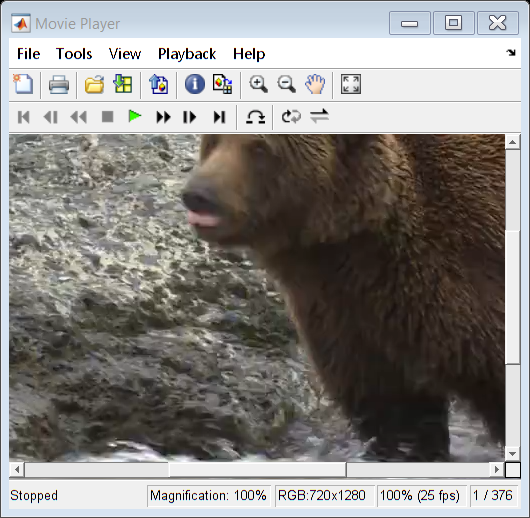

implay("Bear.mp4")

frame_1 = read(BearVideo,1);
frame_30 = read(BearVideo,30);
frame_122 = read(BearVideo,122);
frame_200 = read(BearVideo,200);

[BW,maskedRGB] = createMaskBear(frame_122);

numFrames_Bear= BearVideo.NumFrames;
v_seg= VideoWriter("Boxed_Bear","MPEG-4");

v_seg.FrameRate = BearVideo.FrameRate;
v_seg_comb.FrameRate = BearVideo.FrameRate;
%open(v_seg);
bboxes = [];
idxes = [];

    



for i = 1 : 366
    frame = read(BearVideo,i);
    idx = string(i);
    while strlength(idx) ~= 3
        idx = append("0",idx);
    end
    %imwrite(frame,"Bear-"+idx+".png");
    [Th,maskedRGBImage] = createMaskBear(frame);
    [BW,maskedImage] = segmentImageBear(maskedRGBImage);
    BW = filterRegionsBear(BW);
    %imwrite(BW,"MaskedBear-"+idx+".bmp");
    props = regionprops("table",BW,"BoundingBox");
    BoxedBear =insertShape(frame,"Rectangle",props.BoundingBox,"LineWidth",3,"Color","yellow");
    %writeVideo(v_seg,BoxedBear);
    %bboxes = [bboxes;props];
    %idxes = [idxes;i];

end
%close(v_seg);

idxes

idxes =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10



coords=[];
coords.frames= idxes;
coords.x1 = bboxes.BoundingBox(:,1);
coords.y1 = bboxes.BoundingBox(:,2);
coords.w = bboxes.BoundingBox(:,3);
coords.h = bboxes.BoundingBox(:,4);

coords = struct2table(coords);
writetable(coords,"coords.txt");

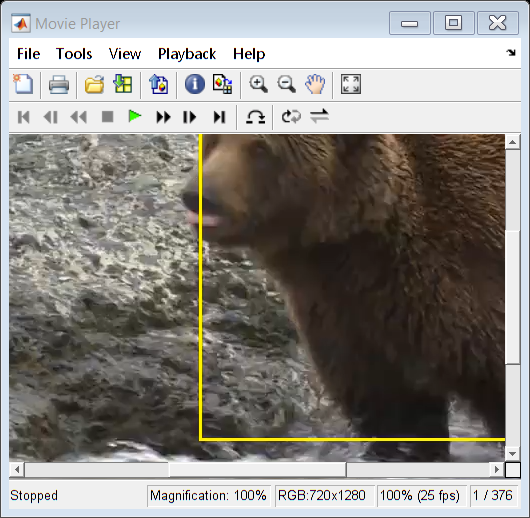

implay("Boxed_Bear.mp4")

binary_vid = VideoReader("Boxed_Bear.mp4");
frame_1 =  logical(imread("MaskedBear-153.bmp"));
frame_38 = logical(im2gray(read(binary_vid,369)));
frame_50 = logical(im2gray(read(binary_vid,50)));
